# **ACTIVIDAD 1.12. Matriz de Transformación Homogénea T**

**Jesús Alejandro Gómez Bautista | A01736171**

## **EJERCICIO II**

**Obtener **la  matriz  de  transformación **homogénea**  **T**  de los siguientes sistemas la cual relacione la posición y orientación del extremo del robot respecto a su sistema de referencia fijo (la base).

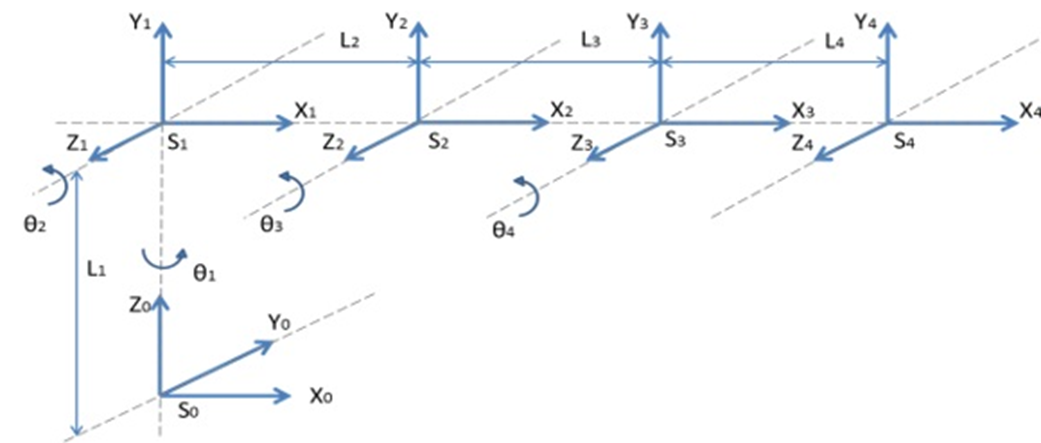

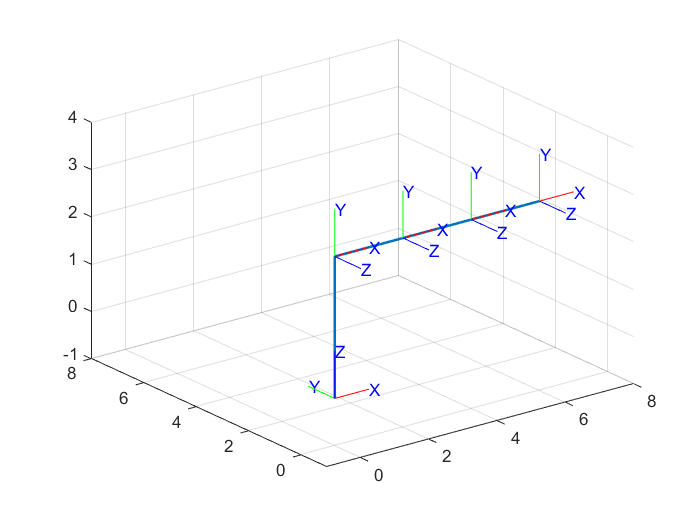

%Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotx(pi/2), [0 0 3]);
H2=SE3([2 0 0]);
H3=SE3([2 0 0]);
H4=SE3([2 0 0]);

H20= H1*H2;
H30= H20*H3; %Matriz de transformación homogenea global de 3 a 0 
H40= H30*H4; %Matriz de transformación homogenea global de 4 a 0 

%Coordenadas de la estructura de translación y rotación
x=[0 0 6];
y=[0 0 0];
z=[0 3 3];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 8 -1 8 -1 4]); grid on;
hold on;

 %Graficamos la trama absoluta o global 
 trplot(H0,'rgb','axis', [-1 8 -1 8 -1 4])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H0, H1,'rgb','axis', [-1 8 -1 8 -1 4])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H1, H20,'rgb','axis', [-1 8 -1 8 -1 4])
% % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H20, H30,'rgb','axis', [-1 8 -1 8 -1 4])
 % % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H30, H40,'rgb','axis', [-1 8 -1 8 -1 4])

## **EJERCICIO III - Parte 1**

**Implementar **el código requerido para generar el cálculo de las matrices **homogéneas (H1, H2, H3, etc.) **y la matriz de **transformación (T) **de cada sistema. Simulando cada una de las transformaciones desde la trama absoluta hasta la trama final. 

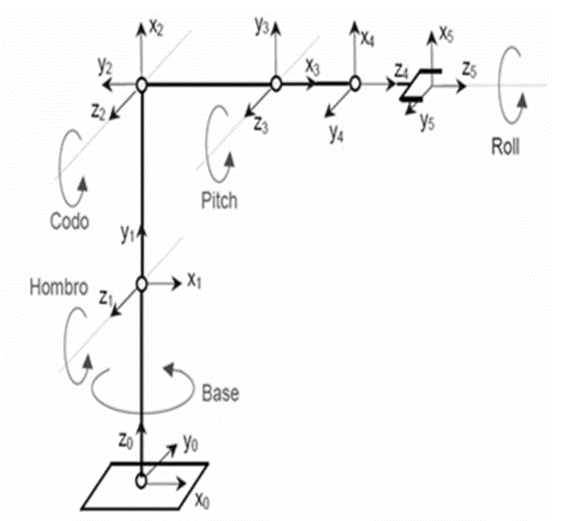

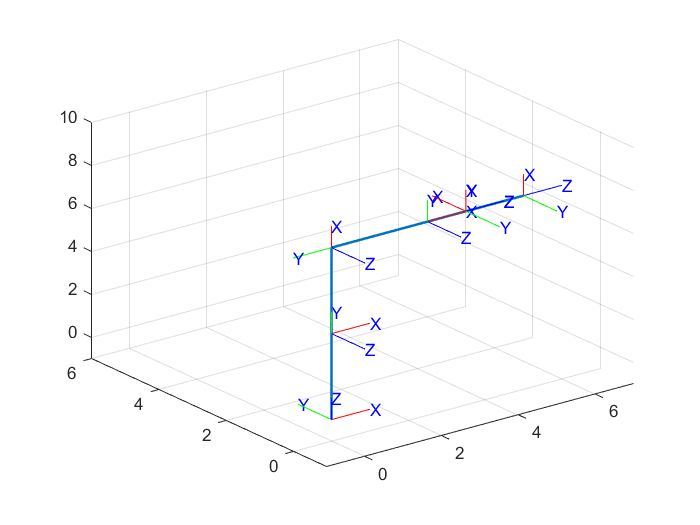

 %Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotx(pi/2), [0 0 4]);
H2=SE3(rotz(pi/2), [0 4 0]);
H3=SE3(rotz(-pi/2),[0 -2.5 0]);
H4=SE3(roty(pi/2), [1 0 0]);
H5=SE3(rotz(pi/2), [0 0 0]);
H6=SE3([0 0 1.5]);

H20= H1*H2;
H30= H20*H3; %Matriz de transformación homogenea global de 3 a 0 
H40= H30*H4; %Matriz de transformación homogenea global de 4 a 0 
H50= H40*H5; %Matriz de transformación homogenea global de 5 a 0 
H60= H50*H6;

%Coordenadas de la estructura de translación y rotación
x=[0 0 5];
y=[0 0 0];
z=[0 8 8];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 7 -1 6 -1 10]); grid on;
hold on;

 %Graficamos la trama absoluta o global 
 trplot(H0,'rgb','axis', [-1 7 -1 6 -1 10])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H0, H1,'rgb','axis', [-1 7 -1 6 -1 10])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H1, H20,'rgb','axis', [-1 7 -1 6 -1 10])
% % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H20, H30,'rgb','axis', [-1 7 -1 6 -1 10])
 % % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H30, H40,'rgb','axis', [-1 7 -1 6 -1 10])
 % % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H40, H50,'rgb','axis', [-1 7 -1 6 -1 10])
 % % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H50, H60,'rgb','axis', [-1 7 -1 6 -1 10])

## **EJERCICIO III - Parte 2**

**Implementar **el código requerido para generar el cálculo de las matrices **homogéneas (H1, H2, H3, etc.) **y la matriz de **transformación (T) **de cada sistema. Simulando cada una de las transformaciones desde la trama absoluta hasta la trama final. 

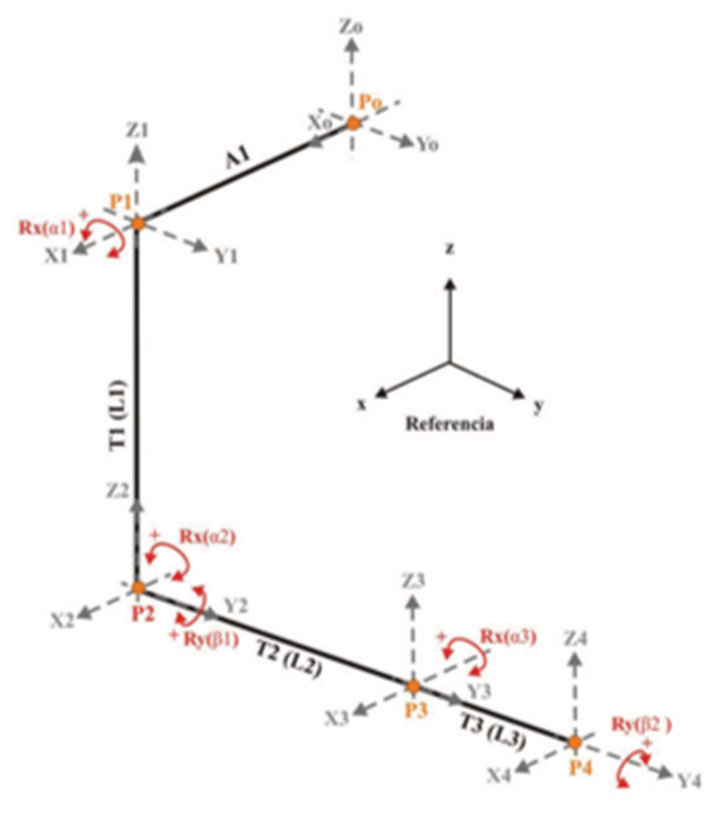

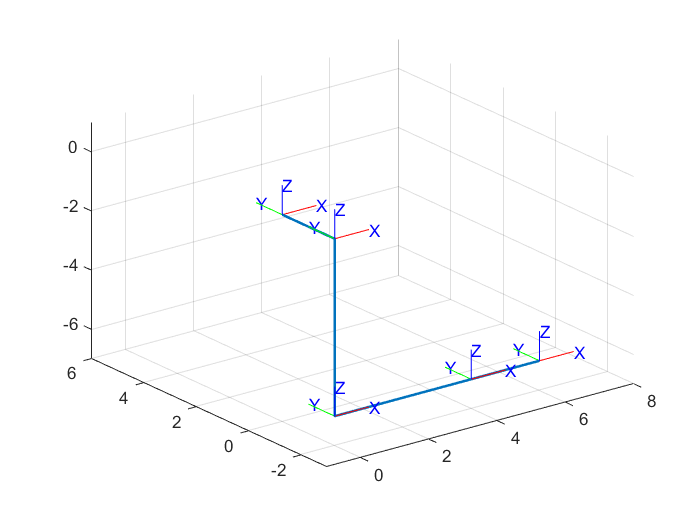

 %Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3([0 -2  0]);
H2=SE3([0  0 -6]);
H3=SE3([4  0  0]);
H4=SE3([2  0  0]);


H20= H1*H2;
H30= H20*H3; %Matriz de transformación homogenea global de 3 a 0 
H40= H30*H4; %Matriz de transformación homogenea global de 4 a 0 


%Coordenadas de la estructura de translación y rotación
x=[ 0  0  0 6];
y=[ 0 -2 -2 -2];
z=[ 0  0 -6 -6];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 8 -3 6 -7 1]); grid on;
hold on;

 %Graficamos la trama absoluta o global 
 trplot(H0,'rgb','axis', [-1 8 -3 6 -7 1])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H0, H1,'rgb','axis', [-1 8 -3 6 -7 1])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H1, H20,'rgb','axis', [-1 8 -3 6 -7 1])
% % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H20, H30,'rgb','axis', [-1 8 -3 6 -7 1])
 % % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H30, H40,'rgb','axis', [-1 8 -3 6 -7 1])

## **EXPLICACIÓN DEL PROCEDIMIENTO LLEVADO A CABO**

Revisamos los elementos desarrollados en el periodo pasado para una actividad introductoria de articulaciones robóticas. En este caso, fue necesario retomar la Ley de la Mano Derecha para entender el sentido y la posición de los ejes, facilitando así la abstracción de cómo deberían comportarse las transformaciones tanto en su rotación como en su traslación.

Hubo algunas complicaciones, especialmente en la implementación de la traslación. Frecuentemente, después de una rotación, al aplicar una traslación, el movimiento resultaba en "retroceder" en lugar de "avanzar" debido al signo de los ejes. Además, determinar la forma del entorno en el que se desarrollaría el trabajo provocó cierta confusión, especialmente al inicio, cuando no se comprendía del todo el funcionamiento del mismo.

En cuanto a la programación, se modificaron las coordenadas de cada estructura y se añadieron matrices de transformación homogéneas locales y globales que cumplían con lo especificado en cada imagen, analizadas mediante la Ley de la Mano Derecha. También se ajustaron las dimensiones de los ejes para una mejor interpretación de los sistemas.